% small signal data


## Run

% simLIN = sim("Version4\version4_lin.slx", "StopTime", "15");
% save("Version4\validation\simLINphaseshift.mat","simLIN",'-mat')
% simDQ = sim("Version4\version4_dq.slx","StopTime", "25");
% save("Version4\validation\simDQphaseshiftLIN.mat","simDQ",'-mat')

% simDQ = load("Version4\validation\simDQphaseshift.mat")

## Linearised values

% to strucs
struc_vsc_vi_dq= simLIN.vi_dq_vsc;
% struc_v_vsc_dq= simABC.vi_dq_vsc;

struc_powers = simLIN.PQ_grid;
struc_vsm = simLIN.VSM;
struc_dc_link = simLIN.DC_link;
struc_qdroop = simLIN.Qdroop_wdc_abc;
struc_wt = simLIN.wind_turbine;
% t_simout = simABC.tout;
    
%        extract data to arrays
t_dc_link = struc_dc_link.time;
DC_voltage = struc_dc_link.signals(1).values;
DC_power_link = struc_dc_link.signals(2).values(:,1);
DC_power_grid = struc_dc_link.signals(2).values(:,2);

i_d_vsc_vec = struc_vsc_vi_dq.signals(2).values(:,1);
i_q_vsc_vec = struc_vsc_vi_dq.signals(2).values(:,2);
v_d_vsc_vec = struc_vsc_vi_dq.signals(1).values(:,1);
v_q_vsc_vec = struc_vsc_vi_dq.signals(1).values(:,2);
t_vsc_vi = struc_vsc_vi_dq.time

t_vsc_vi =          0
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0002



P_vsc = struc_powers.signals(1).values;
Q_vsc = struc_powers.signals(2).values;
t_PQ = struc_powers.time;
VSM_P_Delta = struc_vsm.signals(1).values;
VSM_freq = struc_vsm.signals(2).values;
VSM_theta_deg = struc_vsm.signals(3).values;
t_vsm = struc_vsm.time;

w_wt = struc_wt.signals(3).values;


## DQ values

% big signal 
% struc_v_t_dq= simDQ.v_t_wdc_big;
struc_v_vsc_dq= simDQ.vi_dq_vsc_big;

struc_powers = simDQ.PQ_grid_wdc_big;
struc_vsm = simDQ.VSM_wdc_big;
struc_dc_link = simDQ.DC_link_big;
struc_qdroop = simDQ.Qdroop_wdc_big;
struc_wt = simDQ.wind_turbine_big;


## extract data to arrays

t_dc_link_big = struc_dc_link.time;
DC_voltage_big = struc_dc_link.signals(1).values;
DC_power_link_big = struc_dc_link.signals(2).values(:,1);
DC_power_grid_big = struc_dc_link.signals(2).values(:,2);

% v_d_t_vec_big = struc_v_t_dq.signals(2).values(:,1);
% v_q_t_vec_big = struc_v_t_dq.signals(2).values(:,2);
v_d_vsc_vec_big = struc_v_vsc_dq.signals(1).values(:,1);
v_q_vsc_vec_big = struc_v_vsc_dq.signals(1).values(:,2);
P_vsc_big = struc_powers.signals(1).values;
Q_vsc_big = struc_powers.signals(2).values;

VSM_P_Delta_big = struc_vsm.signals(1).values;
VSM_freq_big = struc_vsm.signals(2).values;
VSM_theta_deg_big = struc_vsm.signals(3).values;

w_wt_big = struc_wt.signals(3).values;


## plotting

plotTitle = "Phaseshift_lin_dq"

plotTitle = "Phaseshift_lin_dq"

figName = plotTitle;
pathName = "Version4\validation\";

## VSM

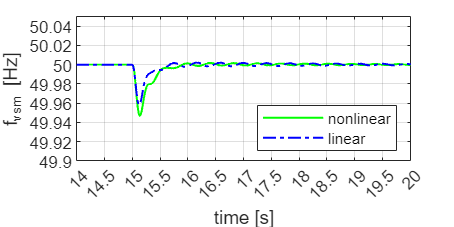

figure('Name','VSM'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 4])
hold on
grid on
box on

plot(t_dc_link_big,VSM_freq_big+50,'g-',LineWidth=1);
plot(t_vsm+14,VSM_freq+50,'b-.',LineWidth=1);
% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([14 20 49.9 50.05])
legend('nonlinear', 'linear','Location','southeast') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('f_{vsm} [Hz]')
ay = gca;
ay.YTick = 49.5:0.02:50.5;
ay.XTick =0:0.5:24;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 4])
plot_file_name = pathName+ "vsm"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = pathName+"vsm"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

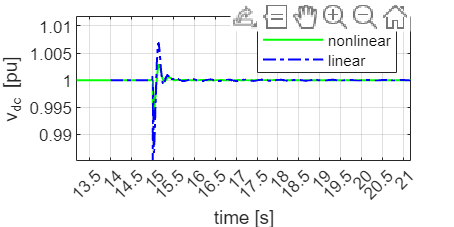

%% DC link
figure('Name','DClinkv'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 4])
hold on
grid on
box on

plot(t_dc_link_big,DC_voltage_big,'g-',LineWidth=1);
plot(t_dc_link+14,(DC_voltage)+1,'b-.',LineWidth=1);

% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([14 20 0.99 1.01])
legend('nonlinear', 'linear') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('v_{dc} [pu]')
ay = gca;
ay.YTick = 0.85:0.005:1.16;
ay.XTick =0:0.5:24;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 4])
plot_file_name = pathName+"DClinkv"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name =pathName+ "DClinkv"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## vsc voltage

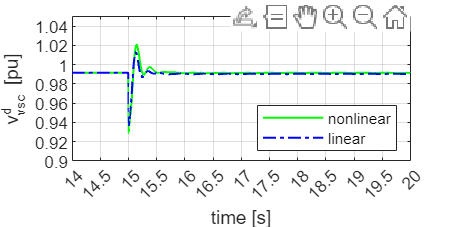


figure('Name','v_vsc'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 4])
hold on
grid on
box on

plot(t_dc_link_big,v_d_vsc_vec_big,'g-',LineWidth=1);
plot(t_vsm+14,v_d_vsc_vec+0.9915,'b-.',LineWidth=1);

% plot(t_vsm,v_q_vsc_vec,'r-',LineWidth=1);
% plot(t_dc_link_big,v_q_vsc_vec_big,'m-.',LineWidth=1);
% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([14 20 0.9 1.05])
legend('nonlinear', 'linear','Location','southeast') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('v^d_{vsc} [pu]')
ay = gca;
ay.YTick = 0:0.02:5;
ay.XTick =0:0.5:25;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 4])
plot_file_name = pathName+"v_vsc"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = pathName+"v_vsc"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## Grid Powers

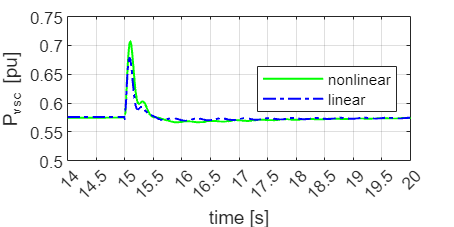


figure('Name','PQ_vsc'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 4])
% grid on


box on
hold on
plot(t_dc_link_big,P_vsc_big,'g-',LineWidth=1);
plot(t_PQ+14,P_vsc+P_t,'b-.',LineWidth=1);
ylabel('P [pu]')
axis([14 20 0.5 0.75])
ay = gca;
ay.YTick = -1:0.05:5;
ay.XTick =0:0.5:24;
grid on
hold off
% 
% plot(t_PQ,Q_vsc,'r-',LineWidth=1);
% plot(t_dc_link_big,Q_vsc_big,'m-.',LineWidth=1);

% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")
grid on
legend('nonlinear', 'linear',Location='east') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('P_{vsc} [pu]')
ay = gca;
ay.YTick = -1:0.05:5;
ay.XTick =0:0.5:24;
hold off


set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 4])
plot_file_name = pathName+"PQ_vsc"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = pathName+"PQ_vsc"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## Turbine

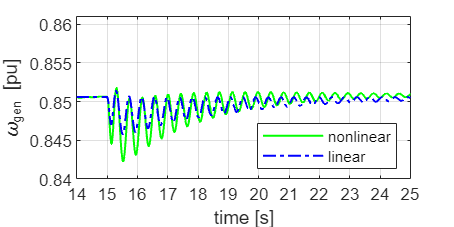


figure('Name','w_tur'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 4])
hold on
grid on
box on


plot(t_dc_link_big,w_wt_big,'g-',LineWidth=1);
plot(t_vsm+14,w_wt+omega_WTR_0_nl,'b-.',LineWidth=1);

% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([14 25 0.84 0.861])
legend('nonlinear', 'linear','Location','southeast') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('\omega_{gen} [pu]')
ay = gca;
ay.YTick = -1:0.005:5;
ay.XTick =0:1:30;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 4])
plot_file_name = pathName+ "w_tur"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name =pathName + "w_tur"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)